close all;
clear;
clc;

% Load sensor measurement data 
load sensorlog_20211124_163739.mat
samplerate=100;

%Put the measurement data into variables
[a] = Acceleration.Variables;
[w] = AngularVelocity.Variables;
[oin] = Orientation.Variables;

% Make sure that the time vector has the minimum length that will be matched with the 
% orientation data (for plotting purpose only )
tfin = min([length(a),length(w),length(oin)]);
t = (1:tfin);

% Define the IMU filter and assign sensors noise covariances
aFilter = imufilter('SampleRate',samplerate); 
aFilter.DecimationFactor=1;
aFilter.GyroscopeNoise          = 0.0002;
aFilter.AccelerometerNoise      = 0.0006;
aFilter.LinearAccelerationNoise = 0.0005;

% Align reference frames 
w(:,1) = -w(:,1);
w(:,2) = w(:,2);
w(:,3) = -w(:,3);
a(:,2) = -a(:,2);
a(:,3) = a(:,3);
qyaw = quaternion([sqrt(2)/2 0 0 sqrt(2)/2]);

#### Fusion processing loop

for i=1:length(t)
    % This is where the IMU fusion function is called
    orientation(i) = aFilter(a(i,:),w(i,:));
    
    % 90 deg rotation to match the phone frame
    orientation(i) = orientation(i)*qyaw;
    
    % Convert quaternion into Euler angles
    eulFilt(i,:)= euler(orientation(i),'ZYX','frame');
end

% Release the system object
release(aFilter)

inityaw = eulFilt(1,1)*180/pi-oin(1,1);

## Visualization

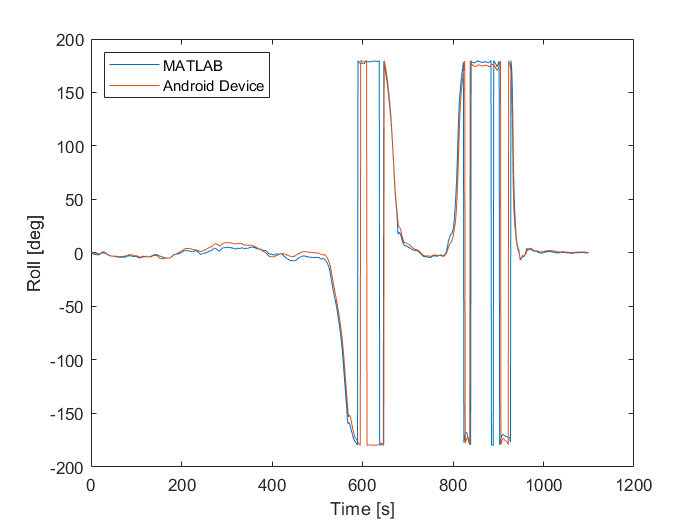

% Plot the estimated orientations in Euler representation along with the orientation already provided by the phone
%% Plot figure for Roll
figure(1)
plot(t,eulFilt(:,3)*180/pi,t,oin((1:tfin),3));
xlabel('Time [s]');
ylabel('Roll [deg]');
legend('MATLAB', 'Android Device','location', 'northwest');

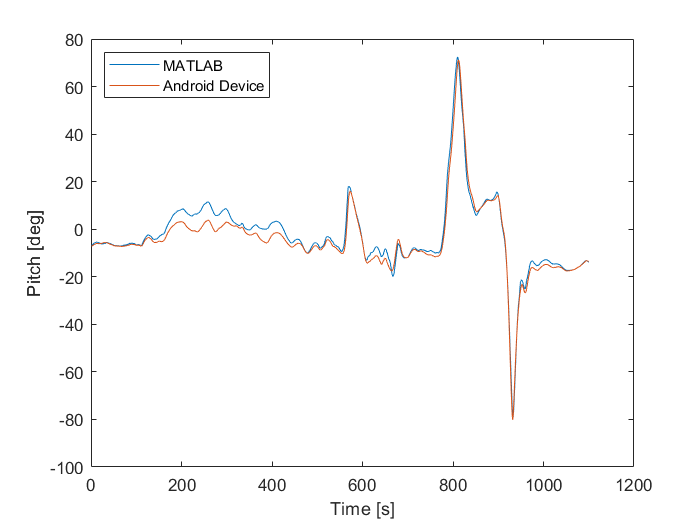

%% Plot figure for Pitch
figure(2)
plot(t,-eulFilt(:,2)*180/pi,t,oin((1:tfin),2));
xlabel('Time [s]');
ylabel('Pitch [deg]');
legend('MATLAB', 'Android Device','location', 'northwest');

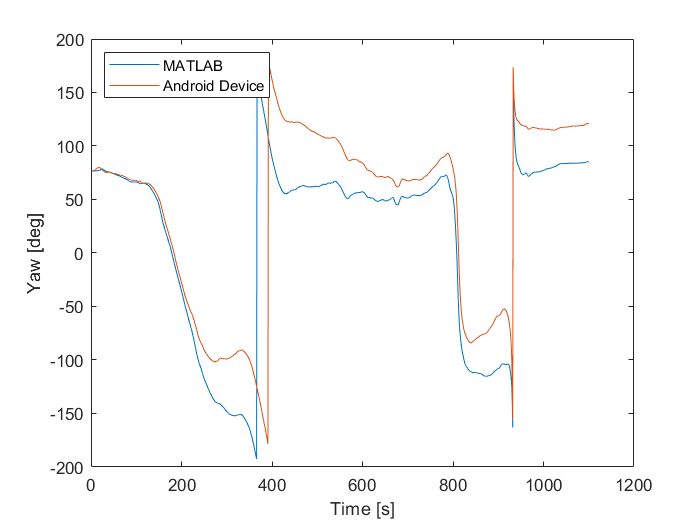

%% Plot figure for Yaw
figure(3)
plot(t,eulFilt(:,1)*180/pi-inityaw,t,oin((1:tfin),1));
xlabel('Time [s]');
ylabel('Yaw [deg]');
legend('MATLAB', 'Android Device', 'location', 'northwest');

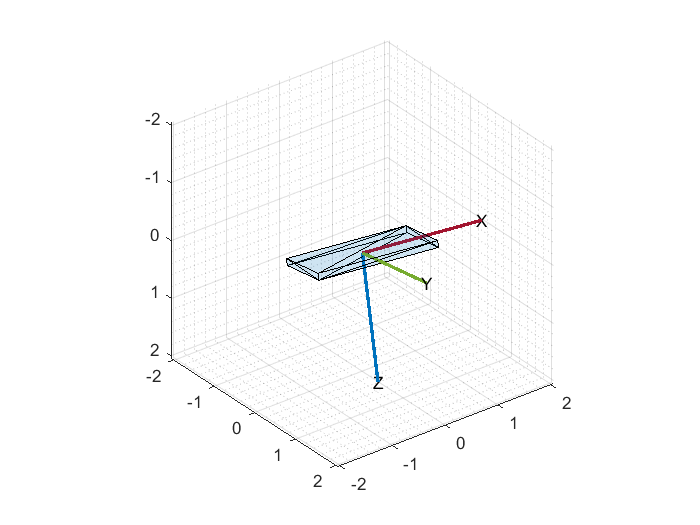

% 3D Visualization of the IMU Filter
figure
pp = poseplot("MeshFileName", "phoneMesh.stl");
for ii=1:size(a,1)
    qimu = aFilter(a(ii,:), w(ii,:));
    set(pp, "Orientation", qimu)
    drawnow 
end